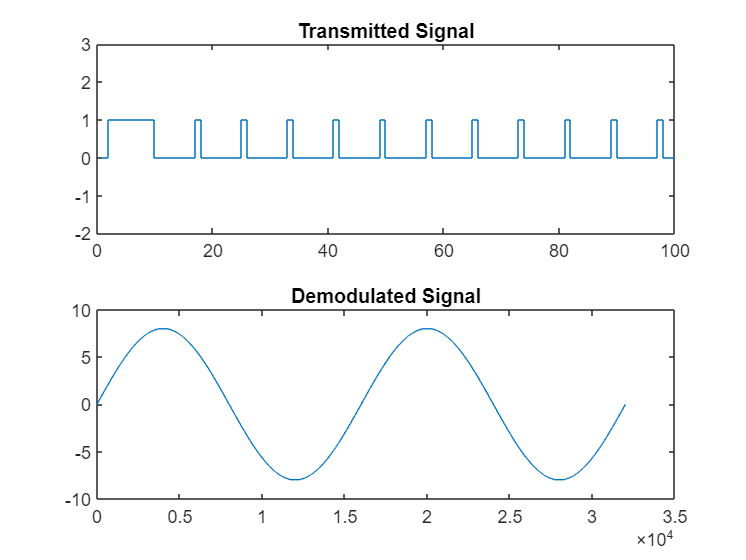

close all;
clear all;
clc;
%%Generation of contionous time signal
fs=200;
t=0:1/fs:1;
f1=2;
f2=2.5;
fm=max(f1,f2);
x=1+sin(2*pi*f1*t)+2*sin(2*pi*f2*t)+cos(2*pi*f2*t);
subplot (221)
plot(t,x,'Linewidth',1.5);
grid on;
title('Input Singal');
xlabel('Time');
ylabel('Amplitude');
subplot(222)
stem(t,x);
grid on;
title('Sampled Singal');
xlabel('Time');
ylabel('Amplitude');
%%Quantization & Encoding
binary=[];
quantized_signal=[];
for n=1:length(t)
        if x(n)>=3 && x(n)<4 q=3.5;
        b='000';
        elseif x(n)>=2 && x(n)<3 q=2.5;
        b='001';
        elseif x(n)>=1 && x(n)<2 q=1.5;
        b='010';
        elseif x(n)>=0 && x(n)<1 q=0.5;
        b='011';
        elseif x(n)>=-1 && x(n)<0 q=-0.5;
        b='100';
        elseif x(n)>=-2 && x(n)<-1 q=-1.5;
        b='101';
        end
        quantized_signal=[quantized_signal,q];
        binary=[binary,b];
end
subplot (223)
plot(t,quantized_signal,'Linewidth',1.5);
grid on;
title('Quantized Singal');
xlabel('Time');
ylabel('Amplitude');
%%decoder
decoder=[];
for n=1:3:length(binary)-2
    if binary(n)=='0' && binary(n+1)=='0' && binary(n+2)=='0'
        decoded=3.5;
    elseif binary(n)=='0' && binary(n+1)=='0' && binary(n+2)=='1'
        decoded=2.5;
    elseif binary(n)=='0' && binary(n+1)=='1' && binary(n+2)=='0'
        decoded=1.5;
    elseif binary(n)=='0' && binary(n+1)=='1' && binary(n+2)=='1'
        decoded=0.5;
    elseif binary(n)=='1' && binary(n+1)=='0' && binary(n+2)=='0'
        decoded=-0.5;
    elseif binary(n)=='1' && binary(n+1)=='0' && binary(n+2)=='1'
        decoded=-1.5; 
    end
    decoder=[decoder,decoded];
end
%%reconstructive filter
fn=2*fm;
F=fir1(20, 2*fm/fs);
filtered_signal=filtfilt(F,1,decoder);
subplot (224)
plot(t,filtered_signal,'Linewidth',1.5);
hold on;
grid on;
title('Rege Singal');
xlabel('Time');
ylabel('Amplitude');